p1 = rand([3 1])*10;

k1 = rand([3 1]);
k1 = k1/norm(k1);

k2 = rand([3 1]);
k2 = k2/norm(k2);

theta1 = rand()*2*pi-pi

theta1 = -0.2293

theta2 = rand()*2*pi-pi

theta2 = -1.0631


p2 = rot(k2, -theta2)*rot(k1,theta1)*p1;

[t1,t2] = subproblem2(p2,p1,k1,k2)

t1 =     0.2293
    1.7194


t2 =    -1.0631
   -0.6806




[t1,t2] = subproblem2_linear(p1,p2,k1,k2)

t1 =    -0.2293   -1.7194


t2 =    -1.0631   -0.6806


sp2_error(p1, p2, k1, k2, t1(1), t2(1))

ans = 9.4832e-15

p1 = rand([3 1]);
p1 = p1 / norm(p1)*10;

k1 = rand([3 1]);
k1 = k1/norm(k1);

k2 = rand([3 1]);
k2 = k2/norm(k2);

p2 = rand([3 1])*10;
p2 = p2 / norm(p2)*10;


t_test_single = linspace(-pi, pi, 100);
[t_test_1, t_test_2] = meshgrid(t_test_single, t_test_single);
e_test = NaN(size(t_test_1));
for i = 1:numel(t_test_1)
    e_test(i) = sp2_error(p1, p2, k1, k2, t_test_1(i), t_test_2(i));
end



[t1,t2] = subproblem2_linear(p1,p2,k1,k2)

t1 =     0.0875   -0.9168


t2 =    -0.7897    2.8001


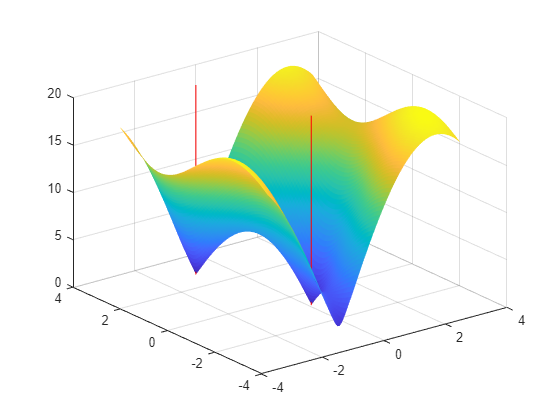

%zline(t1(1), t1(2));

surf(t_test_1, t_test_2, e_test, 'EdgeColor','none')
hold on
h = gca;
plot3([1 1]*t1(1), [1 1]*t2(1), h.ZLim, 'r');
if numel(t1) > 1
    plot3([1 1]*t1(2), [1 1]*t2(2), h.ZLim, 'r');
end
hold off

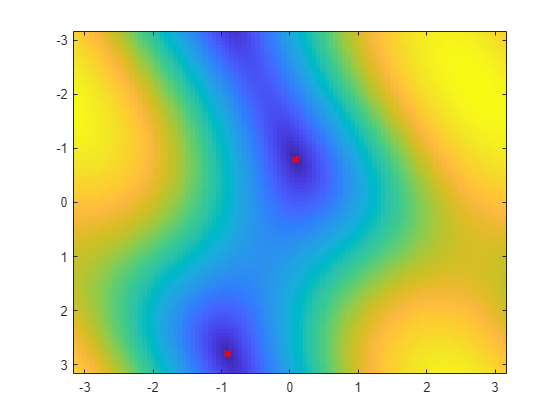


imagesc(t_test_single, t_test_single, e_test)
hold on
plot(t1(1), t2(1), 'rx', 'LineWidth',2)
if numel(t1) > 1
    plot(t1(2), t2(2), 'rx', 'LineWidth',2)
end
hold off

function e = sp2_error(p1, p2, k1, k2, theta1, theta2)
    e = norm(rot(k1, theta1)*p1 - rot(k2, theta2)*p2);
end